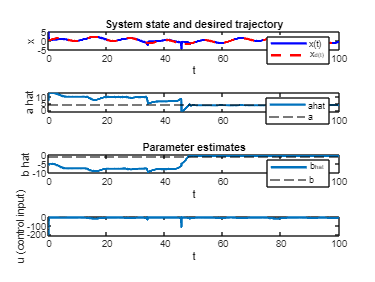

clc; clear; close all;

% Simulation time and initial conditions
tspan = [0 100]; % Time interval for the simulation
initial = [5; 7; -5]; % Initial values for [ x(0) ; a_hat(0) ; b_hat(0) ]

% True but unknown parameters
a = 4; % True value of parameter a
b = -1; % True value of parameter b

% ODE solution setup with specified relative tolerance
opts = odeset('RelTol',1e-5); 
[t, x] = ode45(@(t,x) Dynamics(t,x,a,b), tspan, initial, opts);

% Matrix to store u(t) values
u_vals = zeros(length(t),1);

% Loop to compute u(t) for each t and x(i,:)
for i = 1:length(t)
    x1 = x(i,1); % x(t) value
    a_hat = x(i,2); % Estimated parameter a
    b_hat = x(i,3); % Estimated parameter b

    % Desired trajectory and its derivatives
    x_d = sin(0.1*t(i)) + sin(0.5*t(i)); % Desired position
    x_dd = 0.1*cos(0.1*t(i)) + 0.5*cos(0.5*t(i)); % Desired acceleration

    % Tracking error between desired and actual position
    e = x_d - x1;

    % Regressor vector for the system dynamics
    W = [-x1^2 -x1*sin(x1)];

    % Parameter estimate vector
    phi_hat = [a_hat; b_hat];

    % Proportional control gain
    kp = 2;

    % Control input (u(t)) computation
    u_vals(i) = x_dd + W*phi_hat + kp*e; 
end

% Extracting the components of x(t), a_hat(t), and b_hat(t)
x1 = x(:,1); % Actual state x(t)
a_hat = x(:,2); % Estimated parameter a_hat(t)
b_hat = x(:,3); % Estimated parameter b_hat(t)

% Plotting the results
figure;
% Plot for the system state and desired trajectory
subplot(4,1,1); 
plot(t, x1, 'b', t, sin(0.1*t) + sin(0.5*t), 'r--', 'LineWidth', 2);
xlabel('t'); ylabel('x');
legend('x(t)', 'x_d(t)'); title('System state and desired trajectory');

% Plot for parameter estimate a_hat(t) and true value a
subplot(4,1,2); 
plot(t, a_hat, 'LineWidth', 2); 
hold on;
yline(a, '--k'); % True value of parameter a
ylabel('a hat'); 
legend('ahat', 'a');

% Plot for parameter estimate b_hat(t) and true value b
subplot(4,1,3); 
plot(t, b_hat, 'LineWidth', 2); 
hold on;
yline(b, '--k'); % True value of parameter b
ylabel('b hat'); 
legend('b_hat', 'b');
xlabel('t'); title('Parameter estimates');

% Plot for control input u(t)
subplot(4,1,4); 
plot(t, u_vals, 'LineWidth', 2); 
xlabel('t'); ylabel('u (control input)');


%% === Main Dynamics Function (Contains sub-functions) ===


function xdot = Dynamics(t, x, a, b)
    % State decomposition
    x1 = x(1); % Position x(t)
    a_hat = x(2); % Estimated parameter a
    b_hat = x(3); % Estimated parameter b

    % Regressor vector for the system dynamics
    W = [-x1^2 -x1*sin(x1)];

    % Desired trajectory and its derivatives
    x_d = sin(0.1*t) + sin(0.5*t); % Desired position
    x_dd = 0.1*cos(0.1*t) + 0.5*cos(0.5*t); % Desired acceleration

    % Tracking error between desired and actual position
    e = x_d - x1;

    % Control parameters
    Gamma = 3; % Adaptive gain
    kp = 2; % Proportional gain

    % Estimated parameter vector
    phi_hat = [a_hat; b_hat];

    % Control input (u) computation
    u = x_dd + W*phi_hat + kp*e;

    % System dynamics equations
    x1dot = a*x1^2 + b*x1*sin(x1) + u; % Equation for the position
    a_b_hat_dot = Gamma * W' * e; % Update equations for the parameter estimates

    % Return the state derivatives
    xdot = [x1dot; a_b_hat_dot];
end
